1. Use least squares regression to fit a straight line to the following data (implement the formula from the lectures in Matlab).

x = [0 2 4 6 9 11 12 15 17 19];
y = [5 6 7 6 9 8 8 10 12 12];
n = 10

% calculate mean of x and y:
mean_x = mean(x);
mean_y = mean(y);

% calculate sum of each x and y:
sum_x = sum(x);
sum_y = sum(y);

% calculate power of x and sum of its:
power_x = x.^2;
sum_powerx = sum(power_x);

% calculate sum of xiyi:
xy = x .* y;
xy_sum = sum(xy);

% finding a1 and a0:
a1 = (n * (xy_sum) - sum(x) * sum(y))/(n * sum_powerx - sum_x^2);
a0 = mean_y - a1 * mean_x;

% y of best fit line:
bestfit_y = a0 + x * a1;

% plot graph:
scatter(x, y, 'o', 'MarkerEdgeColor', 'b');
hold on;
plot(x, bestfit_y, 'r');
xlabel('x');
ylabel('y');
title('Least Squares Regression')
legend('Data', 'Fitted Line')
hold off;

2. Calculate the correlation coefficient for the best fit line from question 1.

% calculate power of x and sum of its:
power_y = y.^2;
sum_powery = sum(power_y);

% calculate correlation coefficient
r = (n * xy_sum - sum_x * sum_y)/(sqrt(n * sum_powerx - sum_x .^ 2) * sqrt(n * sum_powery - sum_y .^ 2))

3. Repeat question 1 but use the Matlab built-in functions polyfit to find the equation and polyval to plota.

% use polyfit to find the slope and y-intercept:
a = polyfit(x, y, 1);


   29.6071   32.4881



% plot graph by using polyval:
plot(x, y, 'o', 'MarkerEdgeColor', 'b');
hold on;
X = linspace(0, 19);
Y = polyval(a, X);
plot(X, Y, 'r');
hold off;

4. The following data were gathered to determine the relationship between pressure and temperature of a fixed volume of 1 kg of nitrogen (molar mass of 14.006747 g/mol). The volume is 10m3. Use the ideal gas law equation to determine the universal gas constant, R.

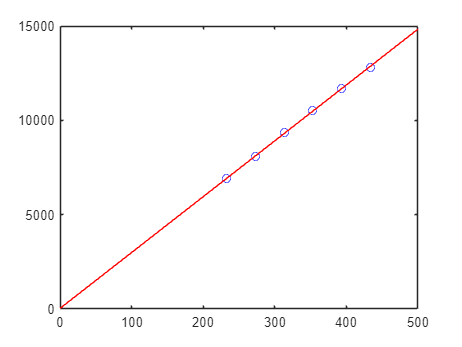

T = [-40 0 40 80 120 160];
p = [6900 8100 9350 10500 11700 12800];

V = 10;
n = (1000 / (14.006747 * 2) );
kelvin = T + 273;

R is approximately 8.293995



% use polyfit to find the slope and y-intercept
b = polyfit(kelvin, p, 1);
disp(b);

% plot graph
close all
plot(kelvin, p, 'o', 'MarkerEdgeColor', 'b');
hold on
line_T = linspace(0, 500);
new_Y = polyval(b, line_T);
plot(line_T, new_Y, 'r');
hold off
% find R:
R = b(1) * V / n;
fprintf('R is approximately %f\n', R);

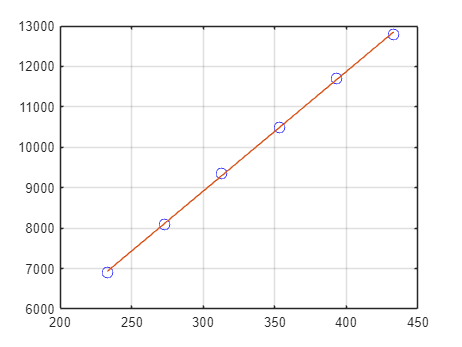


%% Practical Problems 7 Question 4

% Step 1: Define our domain
T = [-40, 0, 40, 80, 120, 160];
p = [6900, 8100, 9350, 10500, 11700, 12800];

V = 10;

kelvin = T + 273;


R is approximately 8.293995


n = (1000 / (14.006747 * 2) );

% Step 2: Find our LOB
a = polyfit(kelvin, p, 1);

% Step 3: Plot graph
plot(kelvin, p, 'bo', 'MarkerSize', 8);
hold on
grid on

    2.0149    1.8326    1.2879    0.7340   -0.0572   -0.8602   -1.4553   -1.8036   -2.3026



Y = polyval(a, kelvin);
plot(kelvin, Y);

% Step 4: Find Universal Gas Constant, R
R = a(1) * V / n;
fprintf('R is approximately %f\n', R);

5. Linearise the following model and use it to estimate the parameters α4 and β4 for the following data. Plot the data with the line of best fit and calculate the correlation coefficient.

x = [0.1 0.2 0.4 0.6 0.9 1.3 1.5 1.7 1.8];

   -2.4733    2.2682



  Columns 1 through 9

         0    0.1857    0.3533    0.5041    0.6393    0.7602    0.8678    0.9631    1.0470

  Columns 10 through 18

    1.1205    1.1843    1.2392    1.2860    1.3252    1.3576    1.3837    1.4040    1.4191

  Columns 19 through 27

    1.4293    1.4352    1.4371    1.4354    1.4305    1.4226    1.4121    1.3992    1.3843

  Columns 28 through 36

    1.3675    1.3490    1.3291    1.3079    1.2856    1.2624    1.2384    1.2138    1.1886

  Columns 37 through 45

    1.1629    1.1370    1.1108    1.0845    1.0581    1.0317    1.0053    0.9791    0.9530

  Columns 46 through 54

    0.9272    0.9016    0.8763    0.8513    0.8267    0.8025    0.7786    0.7552    0.7322

  Columns 55 through 63

    0.7097    0.6876    0.6660    0.6448    0.6241    0.6040    0.5843    0.5651    0.5463

  Columns 64 through 72

    0.5281    0.5103    0.4930    0.4762    0.4599    0.4440    0.4286    0.4136    0.3990

  Columns 73 through 81

    0.3849    0.3713    0.3580    0.3452 

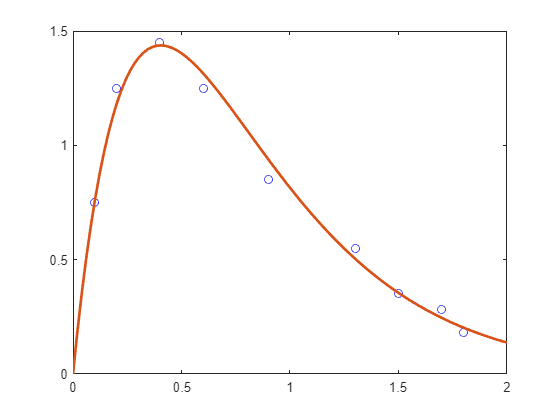

y = [0.75 1.25 1.45 1.25 0.85 0.55 0.35 0.28 0.18];
plot (x, y, 'o', 'MarkerEdgeColor','b');
hold on

ln_y = log(y./x);
disp(ln_y);

a = polyfit(x, ln_y, 1);
r = a(1);
A = exp(a(2));

yfit = @(b) A.*b.*exp(r.*b);
disp(a);

X = linspace(0, 2);

    0.7266    0.5301



disp(yfit(X))
plot(X, yfit(X), 'LineWidth', 2);

    3.3893



6. Try fitting a power equation to the following data on metabolisms of animals then using it to predict the metabolism rate of a 200kg tiger.

mass = [400, 70, 45, 2, 0.3, 0.16];

F = function_handle with value:
    @(x)3.389306511176282*x.^0.726563798967552


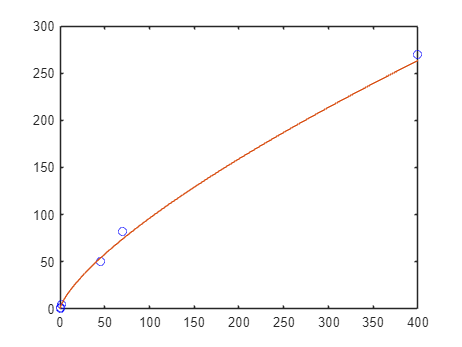

met = [270, 82, 50, 4.8, 1.45, 0.97];
close all
plot(mass, met, 'o', 'MarkerEdgeColor', 'b');
hold on

log_mass = log10(mass);
log_met = log10(met);
a = polyfit(log_mass, log_met, 1);
disp(a);

159.2047


alpha = 10^0.530110845937749;
disp(alpha);

% create equation:
F = @(x) 3.389306511176282 * x.^0.726563798967552

% plot linearization:
fplot(F, [0, 400]);
hold off

% find met from mass of 200kg:
tigerMet = num2str(F(200));
disp(tigerMet);

7. The following data represents bacteria growth. Two models have been proposed for this growth:

Where k is the growth rate and c is the concentration. Fit the data below to both of these models by transforming them into linear relationships and finding the parameters km and cs. Which model fits the data better? Predict the growth of bacteria when c = 2 mg/L. 

c = [0.5 0.8 1.5 2.5 4];
k = [1.1 2.5 5.3 7.6 8.9];
close all
plot(c, k, 'o', 'MarkerEdgeColor','b');
hold on

% find the 1st model:
x1 = 1./c;
y1 = 1./k;

a1 = polyfit(x1, y1, 1);
km1 = 1./a1(2);
cs1 = a1(1)*km1;
model1_func = @(b) (km1.*b)./(cs1+b);

% find the 2nd model:
x2 = 1./c.^2;
y2 = 1./k;

a2 = polyfit(x2, y2, 1);
km2 = 1./a2(2);
cs2 = a2(1)*km2
disp(km2);
disp(cs2);
model2_func = @(b) (km2.*(b.^2))./(cs2+(b.^2));

% plot graph
X = linspace(0.5,4);
plot(X, model1_func(X))
plot(X, model2_func(X))

% Predict the growth of bacteria when c = 2 mg/L
g = model2_func(2);
disp(g);

8. A transportation engineering study was conducted to determine the proper design of bike lanes. Data were gathered on bike lane widths and average distance between bikes and passing cars. The data from 9 streets are: 

% (a) Plot the data
dist = [2.4 1.5 2.4 1.8 1.8 2.9 1.2 3 1.2];
lane = [2.9 2.1 2.3 2.1 1.8 2.7 1.5 2.9 1.5];

close all
plot(dist, lane, 'o', 'MarkerEdgeColor', 'b');
hold on

% (b) Fit a straight line to the data with linear regression. Add this line to the plot. 
a = polyfit(dist, lane, 1);
X = linspace(1, 3);
y = polyval(a, X);
plot(X, y)

xlabel('distance')
ylabel('lane')
title('Linearized Model');
hold off

% (c) If the minimum safe average distance between bikes and passing cars is
% considered to be 1.8m, determine the corresponding minimum lane width.

men = 1.0e+03 *

    0.0096    0.0192    0.0432    0.1009    0.1320    0.2060    0.2848    0.7574    1.5775    3.3860    7.3770


women = 1.0e+03 *

    0.0105    0.0213    0.0476    0.1133    0.1490    0.2301    0.3254    0.8511    1.7718    3.9266    8.1250


% create function

event =          100         200         400         800        1000        1500        2000        5000       10000       20000       42195


q8_func = @(x) a(1).*x + a(2);
ans8 = q8_func(1.8);
disp(ans8);

9. The table below shows the 2015 world record times and holders for outdoor running. Fit a power model for each gender and use it to predict the record time for a half marathon (21,097.5m). Note: the actual records for the half marathon are 3503s (Tadese) and 3909s (Kiplagat) for men and women, respectively.

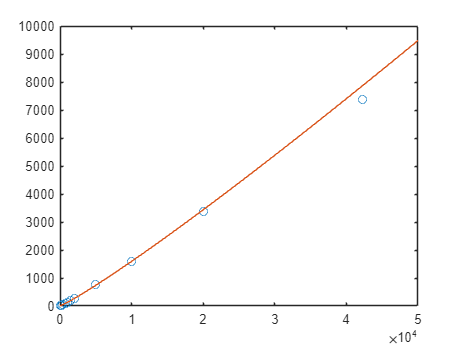

men = [9.58 19.19 43.18 100.90 131.96 206.00 284.79 757.40 1577.53 3386.00 7377.00]
women = [10.49 21.34 47.60 113.28 148.98 230.07 325.35 851.15 1771.78 3926.60 8125.00]
event = [100 200 400 800 1000 1500 2000 5000 10000 20000 42195]

% % men linear:
% aMen = polyfit(event, men, 1);
% XMen = linspace(0, 5e4);
% eqMen = polyval(aMen, XMen);
% 
% % women linear:
% aWomen = polyfit(event, women, 1);
% XWomen = linspace(0, 5e4);
% eqWomen = polyval(aWomen, XWomen);

% men linear:
aMen = polyfit(log10(event), log10(men), 1);
X = linspace(0, 5e4);

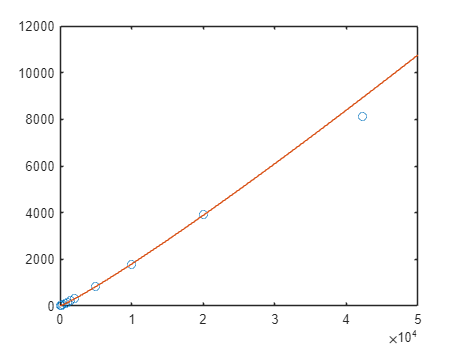

a1 = 10.^aMen(2);
B1 = aMen(1);
powerMen_func = @(x) a1.*(x.^B1);

% % women linear:
aWmen = polyfit(log10(event), log10(women), 1);

a2 = 10.^aWmen(2);
B2 = aWmen(1);

   3.6459e+03



powerWomen_func = @(x) a2.*(x.^B2);

   4.1243e+03




close all
plot(event, men, 'o');
hold on
plot(X, powerMen_func(X));
hold off


plot(event, women, 'o');
hold on
plot(X, powerWomen_func(X));
hold off

disp(powerMen_func(21097));
disp(powerWomen_func(21097));

test

x = [10, 20, 30, 40, 50, 60, 70, 80];
y = [25, 70, 380, 550, 610, 1220, 830, 1450];
z = polyfit(log10(x), log10(y), 1);
disp(z);